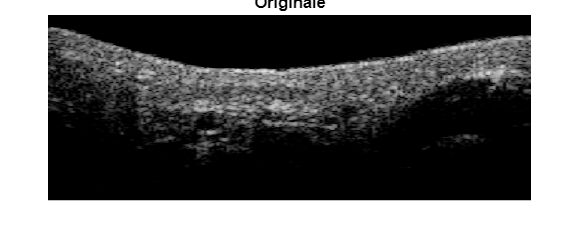

% Import the bscan image
im = imread('Dati elaborati\b-scan estratti\26-07-2023_Luongo_000\26-07-2023_Luongo_000_200.bmp');
imshow(im);title('Originale');

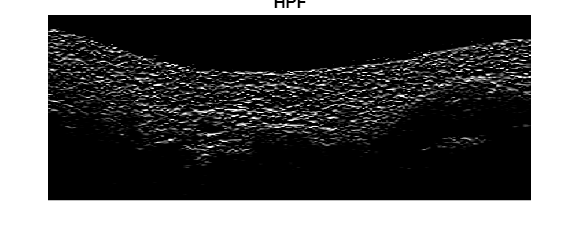

% Apply a high-pass filter to improve contrast
im_filtered = imfilter(im, fspecial('sobel'));
imshow(im_filtered);title('HPF');

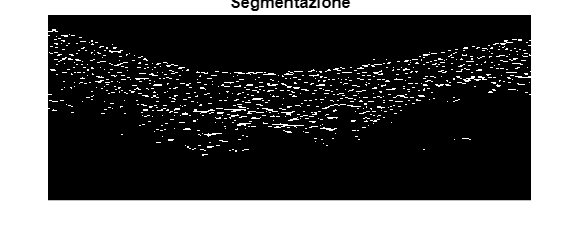

% Apply a threshold to segment the veins
im_segmented = im2bw(im_filtered, 0.5);
imshow(im_segmented);title('Segmentazione');

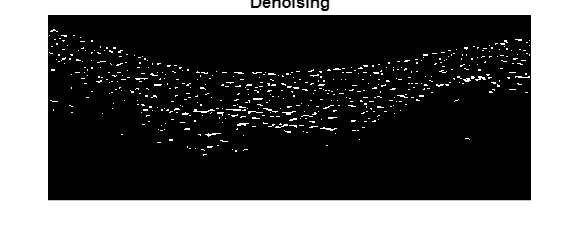

% Remove noise from the segmented image
im_denoised = medfilt2(im_segmented, [3 3]);
imshow(im_denoised);title('Denoising');

% Recognize the vein patterns
patterns = vein_pattern_recognition(im_denoised);

Unrecognized function or variable 'vein_pattern_recognition'.

imshow(patterns);title('Vein patterns');